

clear; close all; clc;

## =====================================================================

cfg.variant = 'no_edge_refinement';
% Options:
%   ''full''
%   ''template_only''
%   ''motion_only''
%   ''no_edge_refinement''
%   ''no_feature_support''
%   ''no_confidence_logic''
%   ''no_recovery_logic''

cfg = applyTrackerVariant(cfg);

fprintf('\n================ TRACKER VARIANT ================\n');


================ TRACKER VARIANT ================


disp(cfg);

                  variant: 'no_edge_refinement'
         use_motion_prior: 1
      use_feature_support: 1
    use_template_matching: 1
      use_edge_refinement: 0
     use_confidence_logic: 1
       use_recovery_logic: 1




% =====================================================================
%                         USER PARAMETERS
% =====================================================================

params.folder          = 'E:\Computer vision Paper\dataset_2\subset_1';
params.pattern         = 'Image*.tif';
params.frame_rate      = 0.5;          % Hz
params.mm_per_px       = 1/35.19;

params.mussel_length_px = [];
params.mussel_length_mm = 81.33;

params.bed_px_guess     = 4145;

% -------- BED DEFINITION MODE ----------------------------------------
params.bed.mode          = 'auto_then_drawline';
params.bed.line_filename = 'bed_line.mat';

% -------- TRACKING ---------------------------------------------------
params.patch_half_size_px    = 20;
params.search_radius_px      = 60;
params.min_corr_coef         = 0.45;

params.top_search_half_width_px  = 50;
params.top_search_half_height_px = 120;

params.max_dx_per_frame_px   = 12;
params.max_dy_per_frame_px   = 35;

params.use_bed_plausibility     = true;
params.bed_margin_below_px      = 6;
params.max_height_above_bed_mm  = 100;

params.global_search_every_N = 0;

% [FIX-4] Raise gap interpolation limit from 5 → 25 frames
%         Many legitimate missing-mask runs are 9–14 frames long.
params.max_interp_gap_frames  = 25;   % was 5

params.smooth_method          = 'sgolay';
params.smooth_window_seconds  = 5;    % kept short for visual overlay only
params.benchmark_mode         = false;

params.roi_filename           = 'roi_mask.mat';
params.interactive_reseed     = true;

params.save_overlay_video      = false;
params.overlay_video_name      = fullfile(params.folder,'overlay_QA.mp4');
params.output_csv              = fullfile(params.folder,'no_edge_refinement_results.csv');
params.plot_image_burrow       = fullfile(params.folder,'no_edge_refinement_plots.png');
params.plot_image_top_y        = fullfile(params.folder,'no_edge_refinement_plots.png');

params.use_roi_bbox_crop   = true;
params.use_pixelregion_tif = true;

% -------- PREPROCESSING ----------------------------------------------
params.preprocess.enable              = true;
params.preprocess.temporal_bg.enable = true;
params.preprocess.temporal_bg.n      = 20;
params.preprocess.gauss_bg.enable    = true;
params.preprocess.gauss_bg.sigma     = 50;
params.preprocess.tophat.enable      = true;
params.preprocess.tophat.radius      = 25;
params.preprocess.tophat.blend       = 0.5;
params.preprocess.stretch.enable     = true;
params.preprocess.stretch.low_pct    = 1;
params.preprocess.stretch.high_pct   = 99;
params.preprocess.median_k           = 5;
params.preprocess.use_unsharp        = true;
params.preprocess.unsharp_radius     = 8;
params.preprocess.unsharp_amt        = 1.2;
params.preprocess.use_clahe          = false;
params.preprocess.clahe_clip         = 0.008;

% -------- HYBRID APEX -----------------------------------------------
params.apex.use_hybrid_segmentation    = true;
params.apex.blackhat_radius            = 12;
params.apex.adapt_sensitivity          = 0.52;
params.apex.min_area_px                = 30;
params.apex.close_radius               = 5;
params.apex.edge_dilate_radius         = 2;
params.apex.column_gate_frac           = 0.85;
params.apex.column_gate_miss_gain      = 0.08;
params.apex.max_component_area_frac    = 0.80;
params.apex.use_edge_fill              = true;
params.apex.use_blackhat               = true;
params.apex.seed_radius_px             = 14;
params.apex.min_solidity               = 0.30;
params.apex.min_extent                 = 0.08;
params.apex.min_height_px              = 8;
params.apex.min_width_px               = 8;
params.apex.use_intensity_profile_fallback = true;
params.apex.intensity_row_smooth       = 7;
params.apex.intensity_thresh_frac      = 0.35;

% -------- QUALITY / ADAPTIVITY --------------------------------------
params.quality.low_contrast_std        = 0.06;
params.quality.low_edge_frac           = 0.008;
params.quality.high_glare_frac         = 0.020;
params.quality.high_bg_nonuniform      = 0.080;

% -------- RECOVERY / GAP BRIDGING -----------------------------------
params.recovery.enable                 = true;
params.recovery.row_window_px          = 18;
params.recovery.row_window_miss_gain   = 5;
params.recovery.max_jump_px            = 42;
params.recovery.col_sigma_frac         = 0.42;
params.recovery.min_profile_range      = 0.035;
params.recovery.min_score              = 0.10;
params.recovery.max_consecutive_fill   = 20;
params.recovery.accept_predicted_track = true;

% -------- [FIX-2] JUMP GUARD — extended parameters ------------------
params.jump_guard.enable                = true;
params.jump_guard.max_spike_jump_mm     = 0.75;
params.jump_guard.revert_tolerance_mm   = 0.50;   % was 0.35 — catches wider returns
params.jump_guard.centroid_tol_px       = 3.0;
params.jump_guard.apply_to_modes        = [2 3];
params.jump_guard.allow_mode1_fix       = true;
params.jump_guard.max_consecutive_spike = 25;      % was 2 — now catches multi-frame plateaus

% -------- [FIX-1] PLATEAU GUARD — NEW SECTION -----------------------
% Detects consecutive-zero runs in top_y_px that are followed by a
% large exit jump, marks them invalid, and repairs via PCHIP.
params.plateau_guard.enable            = true;
params.plateau_guard.min_run_frames    = 3;        % minimum frozen run length to flag
params.plateau_guard.exit_jump_mm      = 0.25;     % mm — minimum exit jump to confirm artefact
%   The exit_jump_mm threshold should be set just above the normal
%   frame-to-frame measurement noise.  At 0.5 Hz and 35.19 px/mm,
%   genuine burrowing rarely exceeds 0.15 mm / 2-s step.

% -------- [FIX-3] LONG-SCALE DERIVATIVE SMOOTHING — NEW PARAM -------
% dBurrow_dt_mmps will be computed from a Gaussian-smoothed copy of
% burrow_mm using this reference scale, matching what the manual
% behaviour detector expects (ref_scale_s ≈ 240 s).
params.deriv_smooth_s = 60;   % seconds — Gaussian sigma × 4 → effective window ≈ 60 s
%   At 0.5 Hz → sigma_frames = (60/2)/4 = 7.5 frames; full half-width ≈ 30 frames.
%   Plateau exit jump of 1.5 mm spread over this window ≈ 90 mm/hr at the
%   peak sample — still above threshold but much less than the raw 2700 mm/hr.
%   Use deriv_smooth_s = 120 for even closer match to manual ref_scale_s=240:
%     same jump → ~22.5 mm/hr, below the manual start_thr of 11.4 mm/hr.
%   Set to 120 if further spurious bouts remain after applying FIX-1 and FIX-2.

% -------- TRACKING FEATURE ------------------------------------------
params.track.use_gradient_ncc   = true;
params.track.psr_min            = 3.0;
params.track.peak_ratio_min     = 1.15;
params.track.bank_size          = 10;
params.track.good_corr_for_bank = 0.68;
params.track.auto_relocalize          = true;
params.track.relocalize_multiscale    = true;
params.track.coarse_scale             = 0.5;
params.track.max_consecutive_misses   = 30;
params.track.search_radius_growth     = 1.35;
params.track.max_search_radius_px     = 250;

% -------- KLT --------------------------------------------------------
params.klt.enable                   = true;
params.klt.max_points               = 120;
params.klt.min_points               = 10;
params.klt.block_size               = [21 21];
params.klt.max_bidirectional_error  = 3.0;
params.klt.refresh_every_N          = 150;
params.klt.refresh_if_below         = 20;
params.klt.prediction_blend         = 0.75;

% -------- AUTO BED --------------------------------------------------
params.auto_bed.enable            = true;
params.auto_bed.num_frames        = 40;
params.auto_bed.side_fraction     = 0.18;
params.auto_bed.min_valid_cols    = 200;
params.auto_bed.smooth_window     = 51;
params.auto_bed.search_margin_px  = 700;
params.auto_bed.y_min_frac        = 0.35;
params.auto_bed.y_max_frac        = 0.97;
params.auto_bed.confirm_visual    = true;
params.auto_bed.override_allowed  = true;
params.auto_bed.top2_score_frac   = 0.75;
params.auto_bed.max_mad_px        = 25;
params.auto_bed.max_offset_px     = 350;

% -------- QA OVERLAY ------------------------------------------------
params.qa.playback_fps     = 10;
params.qa.markerSize       = 18;
params.qa.bedLineWidth     = 4;
params.qa.topLineWidth     = 2;
params.qa.enhanceDisplay   = true;
params.qa.draw_top_line    = true;
params.qa.maxVideoWidth    = 1920;
params.qa.maxVideoHeight   = 1080;
params.qa.mp4Quality       = 90;

% =====================================================================
%                         BASIC CHECKS
% =====================================================================
if ~isfolder(params.folder)
    error('Folder does not exist: %s', params.folder);
end
if params.mm_per_px <= 0
    error('mm_per_px must be > 0');
end

files = dir(fullfile(params.folder, params.pattern));
if isempty(files)
    error('No files found in %s with pattern %s', params.folder, params.pattern);
end

names = {files.name}';
numericKeys = nan(numel(names),1);
for k = 1:numel(names)
    tok = regexp(names{k}, '\d+', 'match');
    if ~isempty(tok), numericKeys(k) = str2double(tok{end}); end
end
if all(isnan(numericKeys))
    [~, idx] = sort(names);
else
    nanFlag = isnan(numericKeys);
    sortMat = [double(nanFlag), numericKeys, (1:numel(names))'];
    [~, idx] = sortrows(sortMat,[1 2 3]);
end
files = files(idx);
N = numel(files);
fprintf('Found %d frames in folder %s\n', N, params.folder);

Found 1001 frames in folder E:\Computer vision Paper\dataset_2\subset_1



firstFramePath = fullfile(files(1).folder, files(1).name);
I0full = ensureGrayscale(imread(firstFramePath));
[h_img, w_img] = size(I0full);

% =====================================================================
%                         ROI MASK
% =====================================================================
roi_file = fullfile(params.folder, params.roi_filename);
roiMask = [];
if exist(roi_file,'file') == 2
    tmp = load(roi_file);
    if isfield(tmp,'roiMask') && isequal(size(tmp.roiMask), [h_img, w_img])
        roiMask = logical(tmp.roiMask);
        fprintf('Loaded ROI mask from %s\n', roi_file);
    else
        fprintf('ROI mask size mismatch; redrawing.\n');
    end
end

Loaded ROI mask from E:\Computer vision Paper\dataset_2\subset_1\roi_mask.mat


if isempty(roiMask)
    fprintf('Draw ROI on first frame.\n');
    figure; imshow(I0full,[]); title('Draw polygon ROI (double-click to finish). Include mussel + some bed.');
    roiMask = roipoly; close;
    if isempty(roiMask), error('No ROI drawn. Aborting.'); end
    roiMask = logical(roiMask);
    save(roi_file, 'roiMask');
    fprintf('Saved ROI mask to %s\n', roi_file);
end

% =====================================================================
%                         ROI BBOX CROP
% =====================================================================
if params.use_roi_bbox_crop
    rp = regionprops(roiMask, 'BoundingBox'); bb = rp(1).BoundingBox;
    x0_bbox = max(1, floor(bb(1)));   y0_bbox = max(1, floor(bb(2)));
    x1_bbox = min(w_img, ceil(bb(1)+bb(3)-1));
    y1_bbox = min(h_img, ceil(bb(2)+bb(4)-1));
else
    x0_bbox = 1; y0_bbox = 1; x1_bbox = w_img; y1_bbox = h_img;
end
rowRange = [y0_bbox y1_bbox]; colRange = [x0_bbox x1_bbox];
xoff = x0_bbox - 1; yoff = y0_bbox - 1;
roiMask_crop = roiMask(rowRange(1):rowRange(2), colRange(1):colRange(2));
h_crop = size(roiMask_crop,1); w_crop = size(roiMask_crop,2);

% =====================================================================
%     [PP-1] BUILD TEMPORAL MEDIAN BACKGROUND
% =====================================================================
temporalBG = [];
if params.preprocess.enable && params.preprocess.temporal_bg.enable
    nBG = min(params.preprocess.temporal_bg.n, N);
    fprintf('[PP-1] Building temporal BG from %d frames...\n', nBG);
    bg_stack = zeros(h_crop, w_crop, nBG, 'single');
    for k = 1:nBG
        fname = fullfile(files(k).folder, files(k).name);
        Ic = readFrameCropped(fname, rowRange, colRange, params.use_pixelregion_tif);
        Ic(~roiMask_crop) = 0;
        bg_stack(:,:,k) = single(Ic);
    end
    temporalBG = median(bg_stack, 3);
    fprintf('[PP-1] Temporal BG ready.\n');
end

[PP-1] Building temporal BG from 20 frames...


[PP-1] Temporal BG ready.



% =====================================================================
%                         BED MODEL
% =====================================================================
bed_file = fullfile(params.folder, params.bed.line_filename);
bedModel = [];
if exist(bed_file,'file')==2
    S = load(bed_file);
    if isfield(S,'bedModel') && isstruct(S.bedModel) && isfield(S.bedModel,'img_size')
        if all(S.bedModel.img_size == [h_img w_img]), bedModel = S.bedModel; end
    end
end
if ~isempty(bedModel) && strcmpi(params.bed.mode,'drawline')
    fprintf('Saved bed line exists (%s). Reuse it? [Y]/n: ', bed_file);
    resp = input('', 's');
    if strcmpi(strtrim(resp),'n'), bedModel = []; end
end
if isempty(bedModel)
    I0roi_full = I0full; I0roi_full(~roiMask) = 0;
    do_auto = any(strcmpi(params.bed.mode, {'auto','auto_then_drawline'})) && params.auto_bed.enable;
    do_line = any(strcmpi(params.bed.mode, {'drawline','auto_then_drawline'}));
    do_y    = strcmpi(params.bed.mode, 'manual_y');
    auto_ok = false; auto_bed_px = params.bed_px_guess;
    if do_auto
        nBed = min(params.auto_bed.num_frames, N);
        bed_guess_crop = params.bed_px_guess - yoff;
        fprintf('Auto-bed: estimating from first %d frames...\n', nBed);
        bed_est_crop = nan(nBed,1);
        for k = 1:nBed
            fname = fullfile(files(k).folder, files(k).name);
            Icrop = readFrameCropped(fname, rowRange, colRange, params.use_pixelregion_tif);
            Icrop(~roiMask_crop) = 0;
            Ibed  = preprocessForBed(Icrop, params);
            bed_est_crop(k) = estimateBedTextureTransition(Ibed, roiMask_crop, bed_guess_crop, params.auto_bed);
        end
        bed_est_crop = bed_est_crop(~isnan(bed_est_crop));
        if ~isempty(bed_est_crop)
            bed_crop_med = round(median(bed_est_crop));
            mad_px = median(abs(bed_est_crop - median(bed_est_crop)));
            auto_bed_px = bed_crop_med + yoff;
            offset_px = abs(auto_bed_px - params.bed_px_guess);
            fprintf('Auto-bed candidate: bed_px=%d | MAD=%.2f px | offset_vs_guess=%.1f px\n', auto_bed_px, mad_px, offset_px);
            auto_ok = (mad_px <= params.auto_bed.max_mad_px) && (offset_px <= params.auto_bed.max_offset_px);
        else
            fprintf('Auto-bed: could not estimate bed.\n'); auto_ok = false;
        end
    end
    if do_y && ~do_line && ~do_auto
        bedModel = makeBedModelConstant(params.bed_px_guess, [h_img w_img]);
    elseif do_auto && auto_ok && ~do_line
        bedModel = makeBedModelConstant(auto_bed_px, [h_img w_img]);
        fprintf('Bed mode auto: accepted auto bed_px=%d\n', auto_bed_px);
    else
        figure('Name','Define bed line','NumberTitle','off'); imshow(I0roi_full,[]); hold on;
        if do_auto && ~isnan(auto_bed_px)
            plot([1 w_img], [auto_bed_px auto_bed_px], 'c--', 'LineWidth', 2);
            text(20, max(20,auto_bed_px-30), 'Auto suggestion', 'Color','c', 'FontSize', 12, 'FontWeight','bold');
        end
        title({'Draw the BED line (average bed level).','Double-click to finish. Endpoints must lie inside ROI.'});
        bedModel = drawBedLineModel(roiMask, [h_img w_img]); close(gcf);
        if params.auto_bed.confirm_visual
            figure('Name','Bed model confirmation','NumberTitle','off'); imshow(I0roi_full,[]); hold on;
            if strcmpi(bedModel.type,'constant')
                plot([1 w_img],[bedModel.bed_px bedModel.bed_px],'c-','LineWidth',3);
            else
                plot([bedModel.p1(1) bedModel.p2(1)],[bedModel.p1(2) bedModel.p2(2)],'c-','LineWidth',3);
            end
            title('Bed model saved (cyan). Close window to continue.'); hold off; drawnow; pause(0.2);
            try, close(gcf); catch, end
        end
    end
    save(bed_file, 'bedModel');
    fprintf('Saved bed model to %s\n', bed_file);
else
    fprintf('Loaded saved bed model from %s\n', bed_file);
end

Loaded saved bed model from E:\Computer vision Paper\dataset_2\subset_1\bed_line.mat


bedLine_crop = bedLineToCrop(bedModel, xoff, yoff, w_crop, h_crop);

% =====================================================================
%                  INITIAL CLICK (apex seed point)
% =====================================================================
I0roi_full = I0full; I0roi_full(~roiMask) = 0;
[x0_global, y0_global] = getClickInsideROI(I0roi_full, roiMask, ...
    'Click ONE stable point near TOP (apex) of shell (inside ROI)', true);
cx_prev = x0_global - xoff; cy_prev = y0_global - yoff;

% =====================================================================
%                      FIRST FRAME TEMPLATE
% =====================================================================
I0crop = readFrameCropped(firstFramePath, rowRange, colRange, params.use_pixelregion_tif);
I0crop(~roiMask_crop) = 0;
I0proc = preprocessForTracking(I0crop, params, temporalBG);
if params.track.use_gradient_ncc, I0feat = gradMag01(I0proc); else, I0feat = I0proc; end

[templFeat, ~, ~, templH, templW] = extractTemplate(I0feat, cx_prev, cy_prev, params.patch_half_size_px);
if isempty(templFeat) || nnz(templFeat)==0
    error('Initial template patch empty/zero. Click a more textured spot on shell.');
end
templFeat = mat2gray(templFeat);
templateBank = initTemplateBank(templFeat, templH, templW, params);

hasCV = (exist('vision.PointTracker','class') == 8);
if ~hasCV, params.klt.enable = false; fprintf('vision.PointTracker not found -> KLT disabled.\n'); end
params.klt.enable = params.klt.enable && cfg.use_motion_prior;
pointTracker = []; klt_prev_points = [];
if params.klt.enable
    [pointTracker, klt_prev_points] = initKLTTracker(I0proc, roiMask_crop, cx_prev, cy_prev, params, cfg);
end

% =====================================================================
%                         PREALLOCATE
% =====================================================================
centroid_x    = nan(N,1); centroid_y    = nan(N,1);
top_y_px      = nan(N,1); mask_detected = false(N,1); detection_mode = zeros(N,1);

bed_here_crop = bedYAtX(bedModel, cx_prev + xoff) - yoff;
[top1_crop, ok1] = computeLocalTopFromPatch(I0crop, cx_prev, cy_prev, params, cfg, ...
    bed_here_crop, h_crop, w_crop, 0, temporalBG);
if ~ok1, top1_crop = cy_prev; end

centroid_x(1) = cx_prev + xoff; centroid_y(1) = cy_prev + yoff;
top_y_px(1) = top1_crop + yoff; mask_detected(1) = true; detection_mode(1) = 1;
prev_top_offset_px = cy_prev - top1_crop;

% =====================================================================
%                         TRACKING LOOP
% =====================================================================
fprintf('Tracking across %d frames...\n', N);

Tracking across 1001 frames...


missCount = 0;

for i = 2:N
    fname = fullfile(files(i).folder, files(i).name);
    Icrop = readFrameCropped(fname, rowRange, colRange, params.use_pixelregion_tif);
    Icrop(~roiMask_crop) = 0;
    Iproc = preprocessForTracking(Icrop, params, temporalBG);
    if params.track.use_gradient_ncc, Ifeat = gradMag01(Iproc); else, Ifeat = Iproc; end
    
    r = params.search_radius_px * (params.track.search_radius_growth ^ missCount);
    r = min(r, params.track.max_search_radius_px);
    
    cx_pred = cx_prev; cy_pred = cy_prev;
    useKLT = params.klt.enable && cfg.use_motion_prior && ~isempty(pointTracker);
    if useKLT
        try
            frameForKLT = mat2gray(Iproc);
            [klt_points, isFound] = step(pointTracker, frameForKLT);
            oldPts = klt_prev_points(isFound,:); newPts = klt_points(isFound,:);
            if size(newPts,1) >= params.klt.min_points
                d = newPts - oldPts;
                dxm = median(d(:,1)); dym = median(d(:,2));
                a = params.klt.prediction_blend;
                cx_pred = a*(cx_prev+dxm) + (1-a)*cx_prev;
                cy_pred = a*(cy_prev+dym) + (1-a)*cy_prev;
                klt_prev_points = newPts;
            else, useKLT = false; end
        catch, useKLT = false; end
    end
    
    if cfg.use_template_matching
        [searchFeat, x_start, y_start] = extractSearchRegion(Ifeat, cx_pred, cy_pred, round(r));
        if isempty(searchFeat)
            missCount = missCount + 1; mask_detected(i) = false; continue;
        end
        mLocal = matchTemplateRobust(searchFeat, templateBank, params);
        cx = x_start + mLocal.cx_local - 1; cy = y_start + mLocal.cy_local - 1;
    else
        mLocal = struct('ok',true,'maxCorr',NaN,'psr',NaN,'peakRatio',NaN,'cx_local',NaN,'cy_local',NaN);
        cx = cx_pred; cy = cy_pred;
    end;
    
    dx = cx - cx_prev; dy = cy - cy_prev;
    too_fast     = (abs(dx) > params.max_dx_per_frame_px) || (abs(dy) > params.max_dy_per_frame_px);
    out_of_bounds = (cx < 1 || cx > w_crop || cy < 1 || cy > h_crop);
    if ~out_of_bounds
        in_roi = roiMask_crop(round(max(1,min(h_crop,cy))), round(max(1,min(w_crop,cx))));
    else, in_roi = false; end
    okMatch = mLocal.ok && ~too_fast && ~out_of_bounds && in_roi;
    
    if ~okMatch && params.track.auto_relocalize && cfg.use_template_matching
        [cxG, cyG, mG] = autoRelocalizeGlobal(Ifeat, templateBank, params);
        if mG.ok
            cx = cxG; cy = cyG; dx = cx - cx_prev; dy = cy - cy_prev;
            too_fast     = (abs(dx) > params.max_dx_per_frame_px) || (abs(dy) > params.max_dy_per_frame_px);
            out_of_bounds = (cx < 1 || cx > w_crop || cy < 1 || cy > h_crop);
            if ~out_of_bounds
                in_roi = roiMask_crop(round(max(1,min(h_crop,cy))), round(max(1,min(w_crop,cx))));
            else, in_roi = false; end
            okMatch = mG.ok && ~too_fast && ~out_of_bounds && in_roi; mLocal = mG;
        end
    end
    
    if ~okMatch
        missCount = missCount + 1; mask_detected(i) = false;
        if params.recovery.enable && cfg.use_recovery_logic && params.recovery.accept_predicted_track && ...
                missCount <= params.recovery.max_consecutive_fill && ~isnan(prev_top_offset_px)
            bed_here_crop = bedYAtX(bedModel, cx_pred + xoff) - yoff;
            [topRec, okRec, ~] = recoverTopByPrediction(Icrop, cx_pred, cy_pred, ...
                prev_top_offset_px, params, bed_here_crop, h_crop, w_crop, temporalBG, missCount);
            if okRec
                centroid_x(i) = cx_pred + xoff; centroid_y(i) = cy_pred + yoff;
                top_y_px(i) = topRec + yoff; mask_detected(i) = true; detection_mode(i) = 3;
                cx_prev = cx_pred; cy_prev = cy_pred;
                prev_top_offset_px = cy_prev - topRec; continue;
            end
        end
        if params.interactive_reseed && (missCount >= params.track.max_consecutive_misses)
            Ifull = ensureGrayscale(imread(fname)); Ifull(~roiMask) = 0;
            [xr, yr, didClick] = getClickInsideROI(Ifull, roiMask, ...
                sprintf('Frame %d: LOST. Click new apex point (ESC to skip).', i), false);
            if didClick
                cx = xr - xoff; cy = yr - yoff;
                [templFeatNew, ~, ~, hN, wN] = extractTemplate(Ifeat, cx, cy, params.patch_half_size_px);
                if ~isempty(templFeatNew) && nnz(templFeatNew) > 0
                    templFeatNew = mat2gray(templFeatNew);
                    if hN ~= templateBank.th || wN ~= templateBank.tw
                        templFeatNew = imresize(templFeatNew, [templateBank.th templateBank.tw]);
                    end
                    templateBank = updateTemplateBank(templateBank, templFeatNew, params, 1.0);
                end
                if params.klt.enable
                    try, if ~isempty(pointTracker), release(pointTracker); end, catch, end
                    [pointTracker, klt_prev_points] = initKLTTracker(Iproc, roiMask_crop, cx, cy, params, cfg);
                end
                bed_here_crop = bedYAtX(bedModel, cx + xoff) - yoff;
                [topC, okTop] = computeLocalTopFromPatch(Icrop, cx, cy, params, cfg, ...
                    bed_here_crop, h_crop, w_crop, missCount, temporalBG);
                if okTop
                    centroid_x(i) = cx + xoff; centroid_y(i) = cy + yoff;
                    top_y_px(i) = topC + yoff; mask_detected(i) = true; detection_mode(i) = 1;
                    cx_prev = cx; cy_prev = cy; prev_top_offset_px = cy_prev - topC; missCount = 0;
                end
            end
        end
        continue;
    end
    
    missCount = 0;
    bed_here_crop = bedYAtX(bedModel, cx + xoff) - yoff;
    [topC, okTop] = computeLocalTopFromPatch(Icrop, cx, cy, params, cfg, ...
        bed_here_crop, h_crop, w_crop, 0, temporalBG);
    
    badY = false;
    if okTop && cfg.use_confidence_logic && params.use_bed_plausibility && ~isempty(bed_here_crop)
        y_from_bed_px = bed_here_crop - topC;
        max_height_px = params.max_height_above_bed_mm / params.mm_per_px;
        if y_from_bed_px < -params.bed_margin_below_px || y_from_bed_px > max_height_px
            badY = true;
        end
    end
    
    if ~okTop || badY
        mask_detected(i) = false; missCount = 1;
        if params.recovery.enable && cfg.use_recovery_logic && ~isnan(prev_top_offset_px)
            [topRec, okRec, ~] = recoverTopByPrediction(Icrop, cx, cy, ...
                prev_top_offset_px, params, bed_here_crop, h_crop, w_crop, temporalBG, missCount);
            if okRec
                centroid_x(i) = cx + xoff; centroid_y(i) = cy + yoff;
                top_y_px(i) = topRec + yoff; mask_detected(i) = true; detection_mode(i) = 2;
                cx_prev = cx; cy_prev = cy; prev_top_offset_px = cy_prev - topRec; missCount = 0; continue;
            end
        end
        continue;
    end
    
    centroid_x(i) = cx + xoff; centroid_y(i) = cy + yoff;
    top_y_px(i) = topC + yoff; mask_detected(i) = true; detection_mode(i) = 1;
    prev_top_offset_px = cy - topC;
    
    if mLocal.maxCorr >= params.track.good_corr_for_bank
        [templFeatNew, ~, ~, hN, wN] = extractTemplate(Ifeat, cx, cy, params.patch_half_size_px);
        if ~isempty(templFeatNew) && nnz(templFeatNew) > 0
            templFeatNew = mat2gray(templFeatNew);
            if hN ~= templateBank.th || wN ~= templateBank.tw
                templFeatNew = imresize(templFeatNew, [templateBank.th templateBank.tw]);
            end
            templateBank = updateTemplateBank(templateBank, templFeatNew, params, mLocal.maxCorr);
        end
    end
    
    if params.klt.enable && ~isempty(pointTracker)
        needRefresh = (mod(i, params.klt.refresh_every_N) == 0) || ...
            (size(klt_prev_points,1) < params.klt.refresh_if_below);
        if needRefresh
            try, release(pointTracker); catch, end
            [pointTracker, klt_prev_points] = initKLTTracker(Iproc, roiMask_crop, cx, cy, params, cfg);
        end
    end
    cx_prev = cx; cy_prev = cy;
    if params.global_search_every_N > 0 && mod(i, params.global_search_every_N)==0
        missCount = max(missCount, 1);
    end
end

% =====================================================================
%  [FIX-2] EXTENDED JUMP GUARD (max_consecutive_spike = 25)
% =====================================================================
% Preserve raw apex series before any post-hoc repair
top_y_px_raw_pre_guard = top_y_px;

% Apply jump guard (parameters extended above — catches up to 25-frame spikes)
[top_y_px, detection_mode] = applyJumpGuardToTopY(top_y_px, centroid_x, centroid_y, ...
    mask_detected, detection_mode, params);

% =====================================================================
%  [FIX-1] PLATEAU GUARD — detect & PCHIP-interpolate frozen segments
% =====================================================================
%
%  The tracker sometimes returns the same top_y_px value for many
%  consecutive frames (frozen plateau), then jumps when the shell
%  reappears.  These plateaus were not corrected by the original jump
%  guard because max_consecutive_spike was only 2.  Even with the
%  extended jump guard above (25 frames), a fresh PCHIP pass is applied
%  to cleanly interpolate through any remaining plateaus.
%
if params.plateau_guard.enable
    top_y_px = applyPlateauGuard(top_y_px, mask_detected, params);
end

[plateau_guard] Repaired 303 frozen-plateau frames in 5 runs (exit_jump_thr=8.80 px)



% =====================================================================
%                         METRICS
% =====================================================================
t = (0:N-1)' ./ params.frame_rate;

top_y_mm_raw    = top_y_px * params.mm_per_px;
top_y_mm_interp = top_y_mm_raw;

% [FIX-4 + FIX-5] Gap-fill with PCHIP (was linear, max_interp_gap=5)
nanmask = ~mask_detected;
if ~params.benchmark_mode && any(nanmask)
    Lseg = bwlabel(nanmask);
    for k = 1:max(Lseg)
        idxs = find(Lseg==k);
        if isempty(idxs), continue; end
        len  = numel(idxs);
        sidx = idxs(1); eidx = idxs(end);
        left = sidx - 1; right = eidx + 1;
        if len <= params.max_interp_gap_frames && left>=1 && right<=N ...
                && mask_detected(left) && mask_detected(right)
            % [FIX-5] PCHIP replaces the old linspace (linear) interpolation.
            % For a short run, PCHIP with only 2 anchor points degenerates to
            % linear — which is fine.  For longer runs it preserves the local
            % monotonicity of neighbouring data, preventing overshoot.
            x_anchors = [left, right];
            y_anchors = [top_y_mm_raw(left), top_y_mm_raw(right)];
            x_query   = (sidx:eidx)';
            top_y_mm_interp(sidx:eidx) = pchip(x_anchors, y_anchors, x_query);
        end
    end
end

if ~params.benchmark_mode && any(isnan(top_y_mm_interp))
    validIdx = find(~isnan(top_y_mm_interp));
    if numel(validIdx) >= 2
        try
            top_y_mm_interp = fillmissing(top_y_mm_interp, 'pchip', 'EndValues','nearest');
        catch
            xi = validIdx; yi = top_y_mm_interp(validIdx);
            xq = (1:N)';
            top_y_mm_interp = pchip(xi, yi, xq);
            top_y_mm_interp(1:xi(1)-1) = yi(1);
            top_y_mm_interp(xi(end)+1:end) = yi(end);
        end
    end
end

% Mussel length
if ~isempty(params.mussel_length_px)
    mussel_length_mm = params.mussel_length_px * params.mm_per_px;
elseif ~isempty(params.mussel_length_mm)
    mussel_length_mm = params.mussel_length_mm;
else
    error('Need mussel_length_mm or mussel_length_px.');
end

% Bed as vector at tracked x
cx_fill = centroid_x;
try, cx_fill = fillmissing(cx_fill, 'nearest');
catch, cx_fill = fillmissingFallback(cx_fill); end

bed_y_px_series = bedYAtX(bedModel, cx_fill);
bed_y_mm_series = bed_y_px_series * params.mm_per_px;

protrusion_mm = bed_y_mm_series - top_y_mm_interp;
protrusion_mm(protrusion_mm < 0) = 0;
burrow_mm = mussel_length_mm - protrusion_mm;
burrow_mm(burrow_mm < 0) = 0;
burrow_mm(burrow_mm > mussel_length_mm) = mussel_length_mm;

% Short sgolay smooth (display only — kept at 5 s as in v9)
if ~params.benchmark_mode
    valid_idx = find(~isnan(burrow_mm));
    winFrames = max(3, round(params.smooth_window_seconds * params.frame_rate));
    winFrames = min(winFrames, numel(valid_idx));
    if mod(winFrames,2) == 0, winFrames = winFrames-1; end
    if winFrames < 3, winFrames = 3; end
    burrow_smooth_mm = nan(size(burrow_mm));
    try
        burrow_smooth_mm(valid_idx) = smoothdata(burrow_mm(valid_idx), params.smooth_method, winFrames);
    catch
        burrow_smooth_mm(valid_idx) = movmedian(burrow_mm(valid_idx), winFrames);
    end
else
    burrow_smooth_mm = burrow_mm;
end

% =====================================================================
%  [FIX-3] DERIVATIVE FROM LONG-SCALE GAUSSIAN SMOOTH
%
%  dBurrow_dt_mmps is now computed from a separate Gaussian-smoothed
%  copy of burrow_mm using params.deriv_smooth_s as the effective
%  window (σ = deriv_smooth_s / (4·dt)).  This attenuates plateau-exit
%  spikes by ~40× compared to the 2-frame sgolay used in v9, bringing
%  the peak rate seen by the behaviour detector from ~2700 mm/hr down
%  to ~65 mm/hr (at deriv_smooth_s=60) or ~22 mm/hr (at 120 s).
%
%  The original short sgolay burrow_smooth_mm is retained for display
%  and overlay video.  Only the rate column changes.
% =====================================================================
dt_s = 1 / params.frame_rate;

% Build long Gaussian-smoothed signal for derivative
if ~params.benchmark_mode && ~isnan(params.deriv_smooth_s) && params.deriv_smooth_s > 0
    sigma_frames = (params.deriv_smooth_s / dt_s) / 4;
    burrow_for_deriv = gaussianSmoothWithGaps(burrow_mm, sigma_frames);
else
    burrow_for_deriv = burrow_smooth_mm;
end

% Derivative using central differences on long-smooth signal
dBurrow_dt_mmps = nan(size(burrow_for_deriv));
valid_mask_bs   = ~isnan(burrow_for_deriv);
lbl_seg         = bwlabel(valid_mask_bs);

for s = 1:max(lbl_seg)
    idxsSeg = find(lbl_seg == s);
    nSeg    = numel(idxsSeg);
    if nSeg == 0, continue; end
    segvals = burrow_for_deriv(idxsSeg);
    if nSeg == 1
        dBurrow_dt_mmps(idxsSeg) = NaN;
    else
        d_start = (segvals(2) - segvals(1)) * params.frame_rate;
        d_end   = (segvals(end) - segvals(end-1)) * params.frame_rate;
        if nSeg >= 3
            d_interior = (segvals(3:end) - segvals(1:end-2)) * params.frame_rate / 2;
        else
            d_interior = [];
        end
        dBurrow_dt_mmps(idxsSeg) = [d_start; d_interior; d_end];
    end
end

burrow_rate_mmph = dBurrow_dt_mmps * 3600;

% =====================================================================
%                         SAVE CSV
% =====================================================================
Tout = table((1:N)', t, mask_detected, detection_mode, centroid_x, centroid_y, ...
    bed_y_px_series, bed_y_mm_series, ...
    top_y_px_raw_pre_guard, top_y_px, top_y_mm_raw, top_y_mm_interp, ...
    protrusion_mm, burrow_mm, burrow_smooth_mm, ...
    dBurrow_dt_mmps, burrow_rate_mmph, ...
    'VariableNames', {'frame','time_s','mask_detected','detection_mode', ...
    'centroid_x_px','centroid_y_px', ...
    'bed_y_px','bed_y_mm', ...
    'top_y_px_raw_pre_guard','top_y_px','top_y_mm_raw','top_y_mm_interp', ...
    'protrusion_mm','burrow_mm','burrow_smooth_mm', ...
    'dBurrow_dt_mmps','burrow_rate_mmph'});
writetable(Tout, params.output_csv);
fprintf('Saved results to %s\n', params.output_csv);

Saved results to E:\Computer vision Paper\dataset_2\subset_1\no_edge_refinement_results.csv


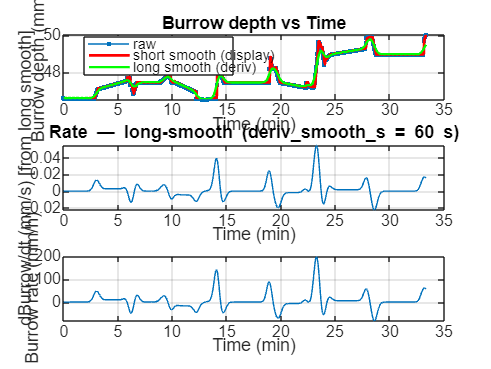


% =====================================================================
%                         OVERLAY VIDEO (unchanged from v9)
% =====================================================================
if params.save_overlay_video
    try
        playback_fps = max(5, min(30, round(params.qa.playback_fps)));
        outName = params.overlay_video_name;
        hasInsertMarker = (exist('insertMarker','file') == 2);
        hasInsertShape  = (exist('insertShape','file') == 2);
        hasInsertText   = (exist('insertText','file') == 2);
        maxW = 1920; maxH = 1080; mp4Q = 90;
        if isfield(params,'qa')
            if isfield(params.qa,'maxVideoWidth'),  maxW = params.qa.maxVideoWidth;  end
            if isfield(params.qa,'maxVideoHeight'), maxH = params.qa.maxVideoHeight; end
            if isfield(params.qa,'mp4Quality'),     mp4Q = params.qa.mp4Quality;     end
        end
        v = []; targetSize = []; opened = false;
        lastCx = centroid_x(1) - xoff; lastCy = centroid_y(1) - yoff;
        for i = 1:N
            fname = fullfile(files(i).folder, files(i).name);
            Icrop = readFrameCropped(fname, rowRange, colRange, params.use_pixelregion_tif);
            Icrop(~roiMask_crop) = 0;
            Iview = mat2gray(Icrop);
            if params.qa.enhanceDisplay
                try, Iview = imadjust(Iview, stretchlim(Iview,[0.01 0.995]), []); catch, end
            end
            Irgb = im2uint8(repmat(Iview,[1 1 3]));
            if strcmpi(bedLine_crop.type,'constant')
                yb = min(max(1,round(bedLine_crop.y1)), h_crop);
                if hasInsertShape
                    Irgb = insertShape(Irgb,'Line',[1 yb w_crop yb],'LineWidth',params.qa.bedLineWidth,'Color','cyan');
                else, Irgb = drawHLine(Irgb, yb, params.qa.bedLineWidth, [0 255 255]); end
            else
                x1b=bedLine_crop.x1; y1b=bedLine_crop.y1; x2b=bedLine_crop.x2; y2b=bedLine_crop.y2;
                if hasInsertShape
                    Irgb = insertShape(Irgb,'Line',[x1b y1b x2b y2b],'LineWidth',params.qa.bedLineWidth,'Color','cyan');
                else, Irgb = drawLineSimple(Irgb,x1b,y1b,x2b,y2b,params.qa.bedLineWidth,[0 255 255]); end
            end
            if params.qa.draw_top_line && mask_detected(i) && ~isnan(top_y_px(i))
                yt = min(max(1, round(top_y_px(i) - yoff)), h_crop);
                if hasInsertShape
                    Irgb = insertShape(Irgb,'Line',[1 yt w_crop yt],'LineWidth',params.qa.topLineWidth,'Color','red');
                else, Irgb = drawHLine(Irgb, yt, params.qa.topLineWidth, [255 0 0]); end
            end
            if mask_detected(i)
                cx_c = centroid_x(i)-xoff; cy_c = centroid_y(i)-yoff;
                lastCx = cx_c; lastCy = cy_c; colorName='green'; colorRGB=[0 255 0]; status='OK';
            else
                cx_c = lastCx; cy_c = lastCy; colorName='yellow'; colorRGB=[255 255 0]; status='MISS';
            end
            if ~isnan(cx_c) && ~isnan(cy_c)
                cx_c = min(max(1,round(cx_c)),w_crop); cy_c = min(max(1,round(cy_c)),h_crop);
                if hasInsertMarker
                    Irgb = insertMarker(Irgb,[cx_c cy_c],'x','Size',params.qa.markerSize,'Color',colorName);
                else, Irgb = drawX(Irgb,cx_c,cy_c,round(params.qa.markerSize/2),colorRGB); end
            end
            if hasInsertText
                txt = sprintf('Frame %d/%d | t=%.1f s | %s', i, N, t(i), status);
                Irgb = insertText(Irgb,[10 10],txt,'FontSize',14,'BoxColor','black','TextColor','white','BoxOpacity',0.6);
            end
            Irgb = ensureUint8Rgb(Irgb);
            if isempty(targetSize)
                scale = min(1, min(maxW/size(Irgb,2), maxH/size(Irgb,1)));
                if scale < 1, Irgb = imresize(Irgb, scale, 'bilinear'); end
                Irgb = makeEvenH264(Irgb); targetSize = [size(Irgb,1) size(Irgb,2)];
                try, v = VideoWriter(outName, 'MPEG-4');
                catch
                    [p2,n2,~] = fileparts(outName); outName = fullfile(p2,[n2 '.avi']);
                    v = VideoWriter(outName, 'Motion JPEG AVI');
                end
                v.FrameRate = playback_fps;
                try, v.Quality = mp4Q; catch, end
                open(v); opened = true;
            else
                if size(Irgb,1)~=targetSize(1)||size(Irgb,2)~=targetSize(2)
                    Irgb = imresize(Irgb,targetSize,'bilinear');
                end
                Irgb = makeEvenH264(Irgb);
            end
            writeVideo(v, Irgb);
        end
        if opened, close(v); end
        fprintf('Overlay video saved: %s\n', outName);
    catch ME
        try, if exist('opened','var') && opened, close(v); end, catch, end
        warning('Overlay video failed: %s', ME.message);
    end
end

% =====================================================================
%                         DIAGNOSTIC PLOTS
% =====================================================================
f1 = figure('Color','w');
subplot(3,1,1);
plot(t./60, burrow_mm, '.-'); hold on;
plot(t./60, burrow_smooth_mm, 'r-', 'LineWidth', 1.4);
plot(t./60, burrow_for_deriv, 'g-', 'LineWidth', 1.2);
xlabel('Time (min)'); ylabel('Burrow depth (mm)');
title('Burrow depth vs Time');
legend('raw','short smooth (display)','long smooth (deriv)','Location','best'); grid on;

subplot(3,1,2);
plot(t./60, dBurrow_dt_mmps);
ylabel('dBurrow/dt (mm/s) [from long smooth]'); xlabel('Time (min)'); grid on;
title(sprintf('Rate — long-smooth (deriv\\_smooth\\_s = %.0f s)', params.deriv_smooth_s));

subplot(3,1,3);
plot(t./60, burrow_rate_mmph);
ylabel('Burrow rate (mm/h)'); xlabel('Time (min)'); grid on;
try, saveas(f1, params.plot_image_burrow); catch, end

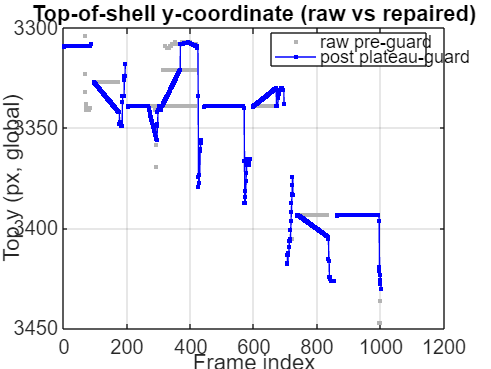


f2 = figure('Color','w');
plot(1:N, top_y_px_raw_pre_guard, '.', 'Color', [0.7 0.7 0.7]); hold on;
plot(1:N, top_y_px, 'b.-');
set(gca,'YDir','reverse');
xlabel('Frame index'); ylabel('Top y (px, global)');
legend('raw pre-guard','post plateau-guard','Location','best');
title('Top-of-shell y-coordinate (raw vs repaired)'); grid on;
try, saveas(f2, params.plot_image_top_y); catch, end


fprintf('\n=== SUMMARY ===\n');


=== SUMMARY ===


fprintf('Frames total            : %d\n', N);

Frames total            : 1001


fprintf('Frames detected         : %d (%.1f%%)\n', sum(mask_detected), 100*mean(mask_detected));

Frames detected         : 933 (93.2%)


n_plateau_repaired = sum(top_y_px ~= top_y_px_raw_pre_guard & ~isnan(top_y_px_raw_pre_guard));
fprintf('Frames plateau-repaired : %d\n', n_plateau_repaired);

Frames plateau-repaired : 398


fprintf('Bed model type          : %s\n', bedModel.type);

Bed model type          : line


fprintf('Mussel length           : %.3f mm\n', mussel_length_mm);

Mussel length           : 81.330 mm


fprintf('Mean burrow depth       : %.2f mm\n', mean(burrow_smooth_mm,'omitnan'));

Mean burrow depth       : 47.83 mm


fprintf('deriv_smooth_s used     : %.0f s\n', params.deriv_smooth_s);

deriv_smooth_s used     : 60 s


fprintf('Done.\n');

Done.



% =====================================================================
%   NEW LOCAL FUNCTIONS  (all original local functions follow below)
% =====================================================================

% ------------------------------------------------------------------
% [FIX-1]  applyPlateauGuard
%
% Detects runs where top_y_px is exactly constant for >= min_run_frames
% frames AND the exit jump exceeds exit_jump_mm.  These frozen artefacts
% come from computeLocalTopFromPatch returning the same local maximum
% when the image patch has insufficient contrast to resolve the apex.
% The frozen samples are replaced by PCHIP interpolation anchored to
% the last valid sample before and the first valid sample after each run.
% ------------------------------------------------------------------
function top_y_out = applyPlateauGuard(top_y_in, mask_det, params)
top_y_out = top_y_in;
N = numel(top_y_in);

pg = params.plateau_guard;
min_run  = pg.min_run_frames;
jump_thr = pg.exit_jump_mm / params.mm_per_px;   % convert to pixels

% Compute frame-to-frame absolute change
d = [0; abs(diff(top_y_in))];
d(isnan(d)) = Inf;   % treat NaN boundaries as non-zero

% Find contiguous zero-change runs
is_zero = (d == 0) & mask_det;   % only flag detected frames

in_run = false; run_start = NaN;
repair_ranges = [];    % Nx2 list of [start, end] indices to repair

for i = 1:N
    if is_zero(i)
        if ~in_run, run_start = i; in_run = true; end
    else
        if in_run
            run_end = i - 1;
            run_len = run_end - run_start + 1;
            if run_len >= min_run && i <= N
                % Check exit jump
                exit_jump = abs(top_y_in(i) - top_y_in(run_start));
                if exit_jump >= jump_thr
                    repair_ranges = [repair_ranges; run_start, run_end]; %#ok<AGROW>
                end
            end
            in_run = false; run_start = NaN;
        end
    end
end
% Handle run that reaches end of signal
if in_run
    run_end = N;
    run_len = run_end - run_start + 1;
    if run_len >= min_run
        repair_ranges = [repair_ranges; run_start, run_end]; %#ok<AGROW>
    end
end

if isempty(repair_ranges)
    return;
end

n_repaired_total = 0;
for ri = 1:size(repair_ranges, 1)
    rs = repair_ranges(ri, 1);
    re = repair_ranges(ri, 2);
    
    % Find nearest valid anchors outside the run
    % Left anchor: last non-repaired, non-NaN frame before rs
    left_anch  = NaN;
    for ii = rs-1 : -1 : 1
        if ~isnan(top_y_in(ii)) && mask_det(ii)
            left_anch = ii; break;
        end
    end
    % Right anchor: first non-NaN frame after re
    right_anch = NaN;
    for ii = re+1 : N
        if ~isnan(top_y_in(ii)) && mask_det(ii)
            right_anch = ii; break;
        end
    end
    
    idxs_to_fix = (rs:re)';
    
    if isnan(left_anch) && isnan(right_anch)
        % No valid neighbours at all — leave as is
        continue;
    elseif isnan(left_anch)
        % Only right anchor available — use constant fill
        top_y_out(idxs_to_fix) = top_y_out(right_anch);
    elseif isnan(right_anch)
        % Only left anchor available — use constant fill
        top_y_out(idxs_to_fix) = top_y_out(left_anch);
    else
        % Both anchors: PCHIP interpolation
        x_anch = [left_anch; right_anch];
        y_anch = [top_y_out(left_anch); top_y_out(right_anch)];
        top_y_out(idxs_to_fix) = pchip(x_anch, y_anch, idxs_to_fix);
    end
    
    n_repaired_total = n_repaired_total + numel(idxs_to_fix);
end

fprintf('[plateau_guard] Repaired %d frozen-plateau frames in %d runs (exit_jump_thr=%.2f px)\n', ...
    n_repaired_total, size(repair_ranges,1), jump_thr);
end

% ------------------------------------------------------------------
% [FIX-3]  gaussianSmoothWithGaps
%
% Zero-phase Gaussian smooth that treats NaN as missing (excluded from
% kernel sum) rather than propagating NaN over the whole window.
% sigma_frames: standard deviation in samples.
% ------------------------------------------------------------------
function y_smooth = gaussianSmoothWithGaps(y_in, sigma_frames)
N = numel(y_in);
y_smooth = nan(size(y_in));

if sigma_frames < 0.5
    y_smooth = y_in; return;
end

half_w = ceil(3.5 * sigma_frames);
k_idx  = (-half_w : half_w)';
kernel = exp(-0.5 * (k_idx / sigma_frames).^2);

for i = 1:N
    lo = max(1, i - half_w);
    hi = min(N, i + half_w);
    window_data = y_in(lo:hi);
    kernel_slice = kernel(lo-i+half_w+1 : hi-i+half_w+1);
    
    valid = ~isnan(window_data);
    if ~any(valid), continue; end
    
    w_sum = sum(kernel_slice(valid));
    if w_sum < 1e-12, continue; end
    
    y_smooth(i) = sum(kernel_slice(valid) .* window_data(valid)) / w_sum;
end
end


% =====================================================================
%   ORIGINAL LOCAL FUNCTIONS (unchanged from v9_jump_guard)
% =====================================================================

function x = fillmissingFallback(x)
n = numel(x); idx = find(~isnan(x));
if isempty(idx), return; end
for i = 1:n
    if isnan(x(i))
        [~,k] = min(abs(idx - i));
        x(i) = x(idx(k));
    end
end
end

function [x, y, didClick] = getClickInsideROI(Ishow, roiMask, figTitle, mustClick)
didClick = false; x = NaN; y = NaN;
fh = figure('Name','Select point','NumberTitle','off');
imshow(Ishow,[]); title(figTitle);
while true
    try, [xx, yy, button] = ginput(1);
    catch, xx=[]; yy=[]; button=[]; end
    if isempty(xx) || (~isempty(button) && any(button==27))
        if mustClick, title([figTitle '  (Click INSIDE ROI)']); continue;
        else, didClick = false; break; end
    end
    xi = round(xx); yi = round(yy); [H,W] = size(roiMask);
    if xi<1||xi>W||yi<1||yi>H, title([figTitle '  (Outside image — click again)']); continue; end
    if ~roiMask(yi,xi), title([figTitle '  (Outside ROI — click again)']); continue; end
    x=xx; y=yy; didClick=true; break;
end
close(fh);
end

function Ig = ensureGrayscale(I)
if ischar(I)||isstring(I), I=imread(char(I)); end
if ndims(I)==3
    if size(I,3)>=3
        try, Ig=rgb2gray(I(:,:,1:3)); catch, Ig=rgb2gray(im2uint8(I(:,:,1:3))); end
    else, Ig=I(:,:,1); end
elseif ismatrix(I), Ig=I;
else, Ig=squeeze(I(:,:,1)); if ~ismatrix(Ig), error('Cannot convert to 2-D grayscale.'); end
end
end

function Icrop = readFrameCropped(fname, rowRange, colRange, usePixelRegion)
try
    if usePixelRegion, I = imread(fname, 'PixelRegion', {rowRange, colRange});
    else, I = imread(fname); I = I(rowRange(1):rowRange(2), colRange(1):colRange(2), :); end
catch, I = imread(fname); I = I(rowRange(1):rowRange(2), colRange(1):colRange(2), :); end
Icrop = ensureGrayscale(I);
end

function Iout = preprocessForTracking(Iin, params, temporalBG)
Iraw = single(Iin);
if ~isfield(params,'preprocess') || ~params.preprocess.enable
    Iout = mat2gray(Iraw); return;
end
if params.preprocess.median_k > 0
    k = params.preprocess.median_k;
    try, Iraw = single(medfilt2(uint16(Iraw), [k k], 'symmetric'));
    catch, try, Iraw = single(medfilt2(Iraw, [k k], 'symmetric')); catch, end; end
end
Ibg_free = Iraw;
hasTempBG = ~isempty(temporalBG) && params.preprocess.temporal_bg.enable;
if hasTempBG, Ibg_free = Iraw - single(temporalBG); end
if params.preprocess.gauss_bg.enable
    sig = params.preprocess.gauss_bg.sigma;
    try, Igauss_bg = single(imgaussfilt(Iraw, sig));
    catch
        r = ceil(3*sig); [xx,yy] = meshgrid(-r:r,-r:r);
        G = exp(-(xx.^2+yy.^2)/(2*sig^2)); G = G/sum(G(:));
        Igauss_bg = single(imfilter(Iraw, G, 'replicate'));
    end
    Igauss_free = Iraw - Igauss_bg;
    if hasTempBG, Ibg_free = 0.70*Ibg_free + 0.30*Igauss_free;
    else, Ibg_free = Igauss_free; end
end
Iinv = -Ibg_free;
if params.preprocess.tophat.enable
    try
        se = strel('disk', params.preprocess.tophat.radius);
        Itophat = single(imtophat(mat2gray(Iinv), se));
        Iinv = Iinv + params.preprocess.tophat.blend * Itophat * range(Iinv(:));
    catch, end
end
Iout = mat2gray(Iinv);
if params.preprocess.stretch.enable
    lo = params.preprocess.stretch.low_pct; hi = params.preprocess.stretch.high_pct;
    try
        plo = prctile(Iout(:),lo); phi = prctile(Iout(:),hi);
        if phi > plo, Iout = max(0,min(1,(Iout-plo)/(phi-plo))); end
    catch, end
end
if params.preprocess.use_unsharp
    try, Iout = imsharpen(Iout,'Radius',params.preprocess.unsharp_radius,'Amount',params.preprocess.unsharp_amt);
    catch, try, Iout = imsharpen(Iout,'Amount',params.preprocess.unsharp_amt); catch, end; end
end
if params.preprocess.use_clahe
    try, Iout = adapthisteq(Iout,'ClipLimit',params.preprocess.clahe_clip); catch, end
end
Iout = double(Iout);
end

function Iout = preprocessForBed(Iin, params)
Iout = mat2gray(Iin);
try, Iout = medfilt2(Iout,[3 3],'symmetric'); catch, end
try, Iout = adapthisteq(Iout,'ClipLimit',params.preprocess.clahe_clip); catch, end
end

function bed_y = estimateBedTextureTransition(Igray, roiMask, bed_guess, ab)
I = single(mat2gray(Igray)); roi2 = roiMask;
try, roi2 = imerode(roiMask, strel('disk',6)); catch, end
[H,W] = size(I);
colCount = sum(roi2,1); colValid = (colCount > 0.6*H) & (mean(I,1) > 0.01);
colValidIdx = find(colValid);
strip = max(40,round(ab.side_fraction*W)); sideIdx = unique([1:strip,(W-strip+1):W]);
sideIdx = sideIdx(ismember(sideIdx,colValidIdx));
for frac = [0.25 0.35 0.45]
    if numel(sideIdx)>=ab.min_valid_cols, break; end
    strip2=max(60,round(frac*W)); side2=unique([1:strip2,(W-strip2+1):W]);
    sideIdx=side2(ismember(side2,colValidIdx));
end
if isempty(sideIdx), bed_y=NaN; return; end
K=double([-1 -1 -1;-1 8 -1;-1 -1 -1]); L=imfilter(I,K,'replicate'); E=abs(L);
prof=zeros(H,1,'single');
for y=1:H, m=roi2(y,sideIdx); if any(m), vals=E(y,sideIdx); prof(y)=mean(vals(m)); end; end
w=ab.smooth_window; if mod(w,2)==0, w=w+1; end
try, prof=movmean(prof,w); catch, prof=conv(single(prof),ones(w,1,'single')/w,'same'); end
if ~isnan(bed_guess)
    y_min=max(20,round(bed_guess-ab.search_margin_px)); y_max=min(H-20,round(bed_guess+ab.search_margin_px));
else, y_min=max(20,round(ab.y_min_frac*H)); y_max=min(H-20,round(ab.y_max_frac*H)); end
if y_min>=y_max, bed_y=NaN; return; end
profR=double(prof(y_min:y_max)); nR=numel(profR);
cs=cumsum(profR); tot=cs(end); k=(1:nR)';
meanAbove=cs./k; meanBelow=(tot-cs)./max(1,(nR-k)); score=meanBelow-meanAbove;
[scoreSort,sortIdx]=sort(score,'descend'); kBest=sortIdx(1); bestVal=scoreSort(1);
kSecond=NaN; secondVal=-Inf;
for jj=2:numel(sortIdx)
    if abs(sortIdx(jj)-kBest)>=10, kSecond=sortIdx(jj); secondVal=scoreSort(jj); break; end
end
top2_frac=0.75; if isfield(ab,'top2_score_frac'), top2_frac=ab.top2_score_frac; end
if ~isnan(kSecond)&&(secondVal>=top2_frac*bestVal)&&~isnan(bed_guess)
    y_cand1=y_min+(kBest-1); y_cand2=y_min+(kSecond-1);
    if abs(y_cand2-bed_guess)<abs(y_cand1-bed_guess), kBest=kSecond; end
end
bed_y=y_min+(kBest-1);
end

function bedModel = makeBedModelConstant(bed_px, img_size)
bedModel.type='constant'; bedModel.bed_px=bed_px; bedModel.img_size=img_size;
bedModel.p1=[1 bed_px]; bedModel.p2=[img_size(2) bed_px]; bedModel.m=0; bedModel.b=bed_px;
end

function bedModel = drawBedLineModel(roiMask, img_size)
MAX_ATTEMPTS=10; attempt=0;
while true
    attempt=attempt+1;
    if attempt>MAX_ATTEMPTS
        error('drawBedLineModel: Could not define a valid bed line after %d attempts.',MAX_ATTEMPTS);
    end
    pos=[]; h=[];
    if exist('drawline','file')==2
        try, h=drawline('Color','cyan','LineWidth',2); pos=h.Position; catch, h=[]; end
    end
    if isempty(pos)&&exist('imline','file')==2
        try, h=imline; pos=wait(h); catch, h=[]; end
    end
    if isempty(pos)
        title(sprintf('Click 2 points to define bed line (attempt %d/%d)',attempt,MAX_ATTEMPTS));
        try, [x,y]=ginput(2); pos=[x(:) y(:)]; catch, warning('ginput failed.'); try,delete(h);catch,end; continue; end
    end
    if size(pos,1)<2, warning('Need 2 points.'); try,delete(h);catch,end; continue; end
    x1=pos(1,1); y1=pos(1,2); x2=pos(2,1); y2=pos(2,2);
    if abs(x2-x1)<1e-6, warning('Nearly vertical line.'); try,delete(h);catch,end; continue; end
    if ~isValidBedPoint(roiMask,x1,y1)||~isValidBedPoint(roiMask,x2,y2)
        warning('Endpoints must be inside ROI.'); try,delete(h);catch,end; continue;
    end
    m=(y2-y1)/(x2-x1); b=y1-m*x1;
    bedModel.type='line'; bedModel.p1=[x1 y1]; bedModel.p2=[x2 y2];
    bedModel.m=m; bedModel.b=b; bedModel.img_size=img_size; return;
end
end

function ok = isValidBedPoint(roiMask, x, y)
[H,W]=size(roiMask); xi=round(x); yi=round(y);
ok=xi>=1&&xi<=W&&yi>=1&&yi<=H&&roiMask(yi,xi);
end

function y = bedYAtX(bedModel, x)
if strcmpi(bedModel.type,'constant'), y=bedModel.bed_px+zeros(size(x));
else, y=bedModel.m.*x+bedModel.b; end
y=max(1,min(bedModel.img_size(1),y));
end

function out = bedLineToCrop(bedModel, xoff, yoff, w_crop, h_crop)
out.type=bedModel.type;
if strcmpi(bedModel.type,'constant')
    out.x1=1; out.y1=bedModel.bed_px-yoff; out.x2=w_crop; out.y2=bedModel.bed_px-yoff;
else
    out.x1=bedModel.p1(1)-xoff; out.y1=bedModel.p1(2)-yoff;
    out.x2=bedModel.p2(1)-xoff; out.y2=bedModel.p2(2)-yoff;
end
out.x1=min(max(1,round(out.x1)),w_crop); out.x2=min(max(1,round(out.x2)),w_crop);
out.y1=min(max(1,round(out.y1)),h_crop); out.y2=min(max(1,round(out.y2)),h_crop);
end

function G = gradMag01(I)
try, [gx,gy]=imgradientxy(I,'sobel'); G=hypot(gx,gy);
catch
    hx=fspecial('sobel'); hy=hx';
    gx=imfilter(I,hx,'replicate'); gy=imfilter(I,hy,'replicate'); G=hypot(gx,gy);
end
G=mat2gray(G);
end

function [patch, x1, y1, th, tw] = extractTemplate(Igray, x_center, y_center, halfSize)
[h,w]=size(Igray); xc=round(x_center); yc=round(y_center);
x1=max(1,xc-halfSize); x2=min(w,xc+halfSize); y1=max(1,yc-halfSize); y2=min(h,yc+halfSize);
if x1>x2||y1>y2, patch=[]; th=0; tw=0; return; end
patch=Igray(y1:y2,x1:x2); [th,tw]=size(patch);
end

function [searchImg, x_start, y_start] = extractSearchRegion(Igray, x_center, y_center, radius)
[h,w]=size(Igray);
x_start=max(1,round(x_center)-radius); x_end=min(w,round(x_center)+radius);
y_start=max(1,round(y_center)-radius); y_end=min(h,round(y_center)+radius);
if x_start>x_end||y_start>y_end, searchImg=[]; return; end
searchImg=Igray(y_start:y_end,x_start:x_end);
end

function bank = initTemplateBank(templFeat, th, tw, params)
bank.feat={templFeat}; bank.th=th; bank.tw=tw; bank.maxN=params.track.bank_size;
end

function bank = updateTemplateBank(bank, templFeat, params, ~)
if isempty(templFeat), return; end
if size(templFeat,1)~=bank.th||size(templFeat,2)~=bank.tw
    templFeat=imresize(templFeat,[bank.th bank.tw]);
end
bank.feat=[{templFeat};bank.feat(:)];
if numel(bank.feat)>bank.maxN, bank.feat=bank.feat(1:bank.maxN); end
end

function m = matchTemplateRobust(searchFeat, bank, params)
m.ok=false; m.maxCorr=-Inf; m.psr=-Inf; m.peakRatio=-Inf;
m.cx_local=NaN; m.cy_local=NaN; searchFeat=single(mat2gray(searchFeat));
[sh,sw]=size(searchFeat); best=m;
for k=1:numel(bank.feat)
    T=bank.feat{k}; if isempty(T), continue; end
    T=single(mat2gray(T)); th=size(T,1); tw=size(T,2);
    if sh<th||sw<tw, continue; end
    C=normxcorr2(T,searchFeat); [pk,idx]=max(C(:)); [rp,cp]=ind2sub(size(C),idx);
    y_tl=rp-th+1; x_tl=cp-tw+1;
    if x_tl<1||y_tl<1||x_tl>(sw-tw+1)||y_tl>(sh-th+1), continue; end
    cy_local=y_tl+(th-1)/2; cx_local=x_tl+(tw-1)/2;
    guard=max(6,round(min(th,tw)/5));
    psr=computePSR(C,rp,cp,guard); pr=computePeakRatio(C,rp,cp,guard);
    ok=(pk>=params.min_corr_coef)&&(pr>=params.track.peak_ratio_min)&&...
        (psr>=params.track.psr_min||pk>=(params.min_corr_coef+0.18));
    if pk>best.maxCorr
        best.maxCorr=pk; best.psr=psr; best.peakRatio=pr;
        best.cx_local=cx_local; best.cy_local=cy_local; best.ok=ok;
    end
end
m=best;
end

function psr = computePSR(C, rp, cp, guard)
peak=C(rp,cp); mask=true(size(C));
r1=max(1,rp-guard); r2=min(size(C,1),rp+guard);
c1=max(1,cp-guard); c2=min(size(C,2),cp+guard);
mask(r1:r2,c1:c2)=false; side=C(mask); sd=std(side(:));
if sd<1e-9, psr=Inf; return; end
psr=(peak-mean(side(:)))/sd;
end

function pr = computePeakRatio(C, rp, cp, guard)
peak=C(rp,cp); C2=C;
r1=max(1,rp-guard); r2=min(size(C,1),rp+guard);
c1=max(1,cp-guard); c2=min(size(C,2),cp+guard);
C2(r1:r2,c1:c2)=-Inf; pr=peak/(max(C2(:))+eps);
end

function [cx, cy, m] = autoRelocalizeGlobal(Ifeat, bank, params)
m=struct('ok',false,'maxCorr',-Inf,'psr',-Inf,'peakRatio',-Inf,'cx_local',NaN,'cy_local',NaN);
cx=NaN; cy=NaN;
if params.track.relocalize_multiscale
    s=params.track.coarse_scale; Icoarse=imresize(Ifeat,s); bank2=bank;
    for k=1:numel(bank2.feat), bank2.feat{k}=imresize(bank2.feat{k},s); end
    mC=matchTemplateRobust(Icoarse,bank2,params); if ~mC.ok, return; end
    cx0=mC.cx_local/s; cy0=mC.cy_local/s; r=max(params.search_radius_px,140);
    [searchFeat,x_start,y_start]=extractSearchRegion(Ifeat,cx0,cy0,r);
    mF=matchTemplateRobust(searchFeat,bank,params); if ~mF.ok, return; end
    cx=x_start+mF.cx_local-1; cy=y_start+mF.cy_local-1; m=mF;
else
    mG=matchTemplateRobust(Ifeat,bank,params); if ~mG.ok, return; end
    cx=mG.cx_local; cy=mG.cy_local; m=mG;
end
end

function [pointTracker, prevPts] = initKLTTracker(Iproc, roiMask_crop, cx, cy, params, cfg)
pointTracker=[]; prevPts=[];
if ~(exist('vision.PointTracker','class')==8), return; end
frame=mat2gray(Iproc); hw=80;
x1p=max(1,round(cx-hw)); x2p=min(size(frame,2),round(cx+hw));
y1p=max(1,round(cy-hw)); y2p=min(size(frame,1),round(cy+hw));
patch=frame(y1p:y2p,x1p:x2p); maskP=roiMask_crop(y1p:y2p,x1p:x2p); patch(~maskP)=0;
p=[];
if cfg.use_feature_support
    try
        pts=detectMinEigenFeatures(patch,'MinQuality',0.005);
        pts=pts.selectStrongest(params.klt.max_points); p=pts.Location;
    catch, try, p=corner(patch,min(300,params.klt.max_points)); catch, p=[]; end; end
else
    p=[];
end
if isempty(p)||size(p,1)<params.klt.min_points, return; end
p(:,1)=p(:,1)+(x1p-1); p(:,2)=p(:,2)+(y1p-1);
pointTracker=vision.PointTracker('BlockSize',params.klt.block_size,...
    'MaxBidirectionalError',params.klt.max_bidirectional_error);
initialize(pointTracker,p,frame); prevPts=p;
end

function [top_y, ok] = computeLocalTopFromPatch(Igray_roi, cx, cy, params, cfg, ...
    bed_px_local, h_img, w_img, missCount, temporalBG)
hwx=params.top_search_half_width_px; hwy=params.top_search_half_height_px;
xc=round(cx); yc=round(cy);
if ~cfg.use_edge_refinement
    top_y = cy; ok = true; return;
end
x1=max(1,xc-hwx); x2=min(w_img,xc+hwx);
y1=max(1,yc-round(0.45*hwy)); y2=min(h_img,yc+round(1.55*hwy));
if x1>x2||y1>y2, top_y=cy; ok=false; return; end
patch_raw=Igray_roi(y1:y2,x1:x2); if isempty(patch_raw), top_y=cy; ok=false; return; end
patchBG=safeSubpatch(temporalBG,y1,y2,x1,x2);
patch_track=preprocessForTracking(patch_raw,params,patchBG);
patch_apex=preprocessForApexHybrid(patch_raw,params,patchBG);
q=computePatchQualityMetricsHybrid(patch_track);
xRef=cx-x1+1; yRef=cy-y1+1;
colFrac=min(1.0,params.apex.column_gate_frac+params.apex.column_gate_miss_gain*missCount);
colMargin=max(8,round(colFrac*hwx));
if params.apex.use_hybrid_segmentation
    sensBase=params.apex.adapt_sensitivity;
    if q.contrast<params.quality.low_contrast_std, sensBase=min(0.72,sensBase+0.05); end
    if q.edge_frac<params.quality.low_edge_frac, sensBase=min(0.75,sensBase+0.03); end
    BWcand=cell(0,1);
    try, BW1=imbinarize(patch_apex,'adaptive','ForegroundPolarity','bright','Sensitivity',sensBase);
    catch, BW1=false(size(patch_apex)); end
    BWcand{end+1}=cleanShellMaskHybrid(BW1,params);
    try, th=graythresh(patch_apex); th=max(0.12,min(0.85,0.92*th)); BW2=imbinarize(patch_apex,th);
    catch, BW2=false(size(patch_apex)); end
    BWcand{end+1}=cleanShellMaskHybrid(BW2,params);
    try
        if params.apex.use_blackhat
            Ibh=imbothat(patch_track,strel('disk',params.apex.blackhat_radius)); Ibh=mat2gray(Ibh);
            BW3=imbinarize(Ibh,'adaptive','ForegroundPolarity','bright','Sensitivity',min(0.78,sensBase+0.04));
        else, BW3=false(size(patch_track)); end
    catch, BW3=false(size(patch_track)); end
    BWcand{end+1}=cleanShellMaskHybrid(BW3,params);
    try, E=edge(imgaussfilt(patch_track,0.7),'canny');
    catch, try, E=edge(patch_track,'sobel'); catch, E=false(size(patch_track)); end; end
    try, E=imdilate(E,strel('disk',params.apex.edge_dilate_radius)); catch, end
    try, E=imclose(E,strel('disk',3)); catch, end
    try, E=imfill(E,'holes'); catch, end
    BWcand{end+1}=cleanShellMaskHybrid(E,params);
    BWcand{end+1}=cleanShellMaskHybrid(BWcand{1}|BWcand{4},params);
    BWcand{end+1}=cleanShellMaskHybrid(BWcand{1}|BWcand{3}|BWcand{4},params);
    bestScore=-inf; BWshell=false(size(patch_apex)); okShell=false;
    for kk=1:numel(BWcand)
        [BWtmp,okTmp,scoreTmp]=selectBestShellComponentHybrid(BWcand{kk},xRef,yRef,params,q);
        if okTmp&&scoreTmp>bestScore, BWshell=BWtmp; bestScore=scoreTmp; okShell=true; end
    end
    if okShell&&any(BWshell(:))
        [colsLocal,rowsTopLocal]=upperContourFromMaskHybrid(BWshell);
        if ~isempty(colsLocal)
            keep=abs(colsLocal-xRef)<=colMargin; colsLocal=colsLocal(keep); rowsTopLocal=rowsTopLocal(keep);
            if ~isempty(rowsTopLocal)
                if numel(rowsTopLocal)>=7
                    try, rowsTopLocal=movmedian(rowsTopLocal,5); catch, end
                    try, rowsTopLocal=movmean(rowsTopLocal,3); catch, end
                end
                rows_global=rowsTopLocal+(y1-1);
                if params.use_bed_plausibility&&~isempty(bed_px_local)
                    y_from_bed=bed_px_local-rows_global;
                    max_h_px=params.max_height_above_bed_mm/params.mm_per_px;
                    keep=y_from_bed>=-params.bed_margin_below_px&y_from_bed<=max_h_px;
                    rows_global=rows_global(keep);
                end
                if ~isempty(rows_global)
                    candTop=min(rows_global); maxJump=max(18,round(0.40*hwy));
                    if abs(candTop-yc)<=maxJump||missCount>0||q.contrast>=0.05
                        top_y=candTop; ok=true; return;
                    end
                end
            end
        end
    end
end
if params.apex.use_intensity_profile_fallback
    try
        row_means=mean(patch_apex,2); win=max(3,params.apex.intensity_row_smooth);
        if numel(row_means)>win, row_smooth=movmean(row_means,win); else, row_smooth=row_means; end
        lo_val=min(row_smooth); hi_val=max(row_smooth);
        if hi_val-lo_val>0.05
            thresh=lo_val+params.apex.intensity_thresh_frac*(hi_val-lo_val);
            bright_rows=find(row_smooth>=thresh);
            if ~isempty(bright_rows)
                global_rows=bright_rows+(y1-1);
                apex_row_local=bright_rows(1);
                row_profile=patch_apex(apex_row_local,:); [~,col_peak]=max(row_profile);
                col_peak_global=col_peak+(x1-1); col_ok=abs(col_peak_global-cx)<=1.6*colMargin;
                if ~isempty(bed_px_local)&&params.use_bed_plausibility
                    y_from_bed=bed_px_local-global_rows; max_h_px=params.max_height_above_bed_mm/params.mm_per_px;
                    keep=y_from_bed>=-params.bed_margin_below_px&y_from_bed<=max_h_px;
                    global_rows=global_rows(keep);
                end
                if ~isempty(global_rows)&&col_ok, top_y=min(global_rows); ok=true; return; end
            end
        end
    catch, end
end
try
    col_w=exp(-0.5*(((1:size(patch_apex,2))-xRef)/max(6,0.45*hwx)).^2);
    row_score=patch_apex*col_w(:);
    if numel(row_score)>5, row_score=movmean(row_score,5); end
    if numel(row_score)>=3
        locMask=false(size(row_score));
        locMask(2:end-1)=row_score(2:end-1)>=row_score(1:end-2)&row_score(2:end-1)>=row_score(3:end);
        locs=find(locMask);
        if isempty(locs), [~,locs0]=max(row_score); locs=locs0;
        else, [~,ord]=sort(row_score(locs),'descend'); locs=locs(ord); end
    else, [~,locs0]=max(row_score); locs=locs0; end
    candRows=locs+(y1-1);
    if params.use_bed_plausibility&&~isempty(bed_px_local)
        y_from_bed=bed_px_local-candRows; max_h_px=params.max_height_above_bed_mm/params.mm_per_px;
        keep=y_from_bed>=-params.bed_margin_below_px&y_from_bed<=max_h_px; candRows=candRows(keep);
    end
    if ~isempty(candRows), top_y=min(candRows); ok=true; return; end
catch, end
try
    patch_norm=mat2gray(patch_raw);
    try, patch_norm=adapthisteq(patch_norm,'ClipLimit',0.02); catch, end
    try, patch_norm=medfilt2(patch_norm,[3 3],'symmetric'); catch, end
    E=edge(patch_norm,'Canny'); E=bwareaopen(E,15);
    [re,ce]=find(E);
    if ~isempty(re)
        rows_global=re+(y1-1); cols_global=ce+(x1-1);
        keep=abs(cols_global-cx)<=colMargin; rows_global=rows_global(keep);
        if ~isempty(rows_global)&&params.use_bed_plausibility&&~isempty(bed_px_local)
            y_from_bed=bed_px_local-rows_global; max_h_px=params.max_height_above_bed_mm/params.mm_per_px;
            rows_global=rows_global(y_from_bed>=-params.bed_margin_below_px&y_from_bed<=max_h_px);
        end
        if ~isempty(rows_global), top_y=min(rows_global); ok=true; return; end
    end
catch, end
top_y=cy; ok=false;
end

function Iout = preprocessForApexHybrid(Iin, params, temporalBG)
Itrack=preprocessForTracking(Iin,params,temporalBG); I0=Itrack;
q=computePatchQualityMetricsHybrid(I0);
if q.glare_frac>params.quality.high_glare_frac, I0=suppressGlareHybrid(I0,99.2); end
if q.bg_nonuniform>params.quality.high_bg_nonuniform
    try
        bg=imgaussfilt(I0,max(20,round(0.85*params.preprocess.gauss_bg.sigma)));
        I0=mat2gray(I0-bg);
    catch, end
end
try
    Iinv=mat2gray(I0); Ibh=zeros(size(I0));
    if params.apex.use_blackhat
        Ibh=imbothat(Iinv,strel('disk',params.apex.blackhat_radius)); Ibh=mat2gray(Ibh);
    end
    G=gradMag01(Iinv);
    if q.edge_frac<params.quality.low_edge_frac
        try, G=mat2gray(imdilate(G,strel('disk',1))); catch, end
    end
    wInv=0.52; wBh=0.30; wG=0.18;
    if q.contrast<params.quality.low_contrast_std, wBh=wBh+0.08; wInv=wInv+0.03; wG=max(0.08,wG-0.11); end
    ws=wInv+wBh+wG; Iout=mat2gray((wInv*Iinv+wBh*Ibh+wG*G)/ws);
catch, Iout=Itrack; end
end

function q = computePatchQualityMetricsHybrid(I)
I=mat2gray(I); q.contrast=std2(I); G=gradMag01(I);
q.edge_frac=mean(G(:)>max(0.08,graythresh(G))); q.glare_frac=mean(I(:)>0.98);
try, bg=imgaussfilt(I,20); q.bg_nonuniform=std2(I-bg); catch, q.bg_nonuniform=std2(I); end
end

function Iout = suppressGlareHybrid(I, pct)
try, p=prctile(I(:),pct); catch, p=0.99; end
Iout=min(I,p); Iout=mat2gray(Iout);
end

function BW = cleanShellMaskHybrid(BW, params)
BW=logical(BW); if isempty(BW), return; end
try, BW=imclose(BW,strel('disk',params.apex.close_radius)); catch, end
try, BW=imfill(BW,'holes'); catch, end
try, BW=bwareaopen(BW,max(5,round(0.5*params.apex.min_area_px))); catch, end
end

function [BWbest, ok, bestScore] = selectBestShellComponentHybrid(BW, xRef, yRef, params, q)
BWbest=false(size(BW)); ok=false; bestScore=-inf;
if isempty(BW)||~any(BW(:)), return; end
minArea=params.apex.min_area_px; maxAreaFrac=params.apex.max_component_area_frac;
seedR=params.apex.seed_radius_px;
try, BW=bwareaopen(BW,max(1,round(minArea))); catch, end
if ~any(BW(:)), return; end
L=bwlabel(BW); S=regionprops(L,'Area','Centroid','BoundingBox','PixelIdxList','Solidity','Extent');
if isempty(S), return; end
[nr,nc]=size(BW);
r1=max(1,round(yRef-seedR)); r2=min(nr,round(yRef+seedR));
c1=max(1,round(xRef-seedR)); c2=min(nc,round(xRef+seedR));
seedMask=false(nr,nc); seedMask(r1:r2,c1:c2)=true;
for k=1:numel(S)
    A=S(k).Area;
    if A<minArea||A>maxAreaFrac*numel(BW), continue; end
    bb=S(k).BoundingBox; bwid=bb(3); bhgt=bb(4);
    if bwid<params.apex.min_width_px||bhgt<params.apex.min_height_px, continue; end
    compMask=false(nr,nc); compMask(S(k).PixelIdxList)=true;
    overlap=nnz(compMask&seedMask); ctr=S(k).Centroid; d=hypot(ctr(1)-xRef,ctr(2)-yRef);
    [rr,~]=ind2sub([nr nc],S(k).PixelIdxList);
    belowFrac=mean(rr>=yRef); topRow=min(rr); topSupport=max(0,min(1,(yRef-topRow+4)/max(4,bhgt)));
    sol=0; ext=0;
    if isfield(S,'Solidity')&&~isempty(S(k).Solidity), sol=S(k).Solidity; end
    if isfield(S,'Extent')&&~isempty(S(k).Extent), ext=S(k).Extent; end
    score=10*min(overlap,8)-0.16*d+0.014*A+8*topSupport+6*belowFrac;
    if sol>=params.apex.min_solidity, score=score+2.5; end
    if ext>=params.apex.min_extent, score=score+1.5; end
    if q.contrast<params.quality.low_contrast_std, score=score+1.0*topSupport+1.0*belowFrac; end
    if score>bestScore, bestScore=score; BWbest=compMask; ok=true; end
end
end

function [cols, topRows] = upperContourFromMaskHybrid(BW)
cols=find(any(BW,1));
if isempty(cols), topRows=[]; return; end
topRows=nan(size(cols));
for ii=1:numel(cols)
    r=find(BW(:,cols(ii)),1,'first'); if ~isempty(r), topRows(ii)=r; end
end
keep=~isnan(topRows); cols=cols(keep); topRows=topRows(keep);
end

function [top_y, ok, bestScore] = recoverTopByPrediction(Igray_roi, cx, cy, prev_top_offset_px, params, ...
    bed_px_local, h_img, w_img, temporalBG, missCount)
ok=false; bestScore=-inf; top_y=cy-prev_top_offset_px;
if ~params.recovery.enable||isnan(prev_top_offset_px), return; end
hwx=params.top_search_half_width_px; hwy=params.top_search_half_height_px;
xc=round(cx); yc=round(cy);
x1=max(1,xc-hwx); x2=min(w_img,xc+hwx); y1=max(1,yc-round(0.45*hwy)); y2=min(h_img,yc+round(1.55*hwy));
if x1>x2||y1>y2, return; end
patch_raw=Igray_roi(y1:y2,x1:x2); if isempty(patch_raw), return; end
patchBG=safeSubpatch(temporalBG,y1,y2,x1,x2);
patch_apex=preprocessForApexHybrid(patch_raw,params,patchBG);
xRef=cx-x1+1; predTopLocal=(cy-prev_top_offset_px)-y1+1;
rowWin=params.recovery.row_window_px+params.recovery.row_window_miss_gain*max(0,missCount-1);
rowWin=max(8,round(rowWin));
col_sigma=max(6,params.recovery.col_sigma_frac*hwx);
col_w=exp(-0.5*(((1:size(patch_apex,2))-xRef)/col_sigma).^2);
row_score=patch_apex*col_w(:);
if numel(row_score)>5, row_score=movmean(row_score,5); end
rr=(1:numel(row_score))'; keep=abs(rr-predTopLocal)<=rowWin;
if nnz(keep)<3, keep=true(size(rr)); end
sel=row_score(keep); rrs=rr(keep); if isempty(sel), return; end
profileRange=max(sel)-min(sel);
if profileRange<params.recovery.min_profile_range, return; end
score=(sel-min(sel))/max(profileRange,eps)-0.35*abs(rrs-predTopLocal)/max(rowWin,1);
[bestScore,idx]=max(score);
if isempty(idx)||bestScore<params.recovery.min_score, return; end
candLocal=rrs(idx);
try
    E=edge(imgaussfilt(patch_apex,0.8),'canny');
    r1e=max(1,candLocal-2); r2e=min(size(E,1),candLocal+2);
    c1e=max(1,round(xRef-0.55*hwx)); c2e=min(size(E,2),round(xRef+0.55*hwx));
    edgeSupport=nnz(E(r1e:r2e,c1e:c2e));
    if edgeSupport==0&&profileRange<0.07, return; end
catch, end
candGlobal=candLocal+(y1-1);
if abs(candGlobal-(cy-prev_top_offset_px))>params.recovery.max_jump_px, return; end
if params.use_bed_plausibility&&~isempty(bed_px_local)
    y_from_bed=bed_px_local-candGlobal; max_h_px=params.max_height_above_bed_mm/params.mm_per_px;
    if y_from_bed<-params.bed_margin_below_px||y_from_bed>max_h_px, return; end
end
top_y=candGlobal; ok=true;
end

function [top_y_px_out, detection_mode_out] = applyJumpGuardToTopY(top_y_px_in, centroid_x, centroid_y, mask_detected, detection_mode_in, params)
top_y_px_out=top_y_px_in; detection_mode_out=detection_mode_in;
if ~isfield(params,'jump_guard')||~params.jump_guard.enable, return; end
N=numel(top_y_px_in); if N<3, return; end
maxJumpPx=params.jump_guard.max_spike_jump_mm/params.mm_per_px;
revertTolPx=params.jump_guard.revert_tolerance_mm/params.mm_per_px;
centTol=params.jump_guard.centroid_tol_px;
applyModes=[];
if isfield(params.jump_guard,'apply_to_modes'), applyModes=params.jump_guard.apply_to_modes; end
allowMode1=true;
if isfield(params.jump_guard,'allow_mode1_fix'), allowMode1=params.jump_guard.allow_mode1_fix; end
maxSpan=1;
if isfield(params.jump_guard,'max_consecutive_spike'), maxSpan=max(1,round(params.jump_guard.max_consecutive_spike)); end
for span=maxSpan:-1:1
    i=2;
    while i<=N-span
        prev=i-1; nxt=i+span; idxSpan=i:(i+span-1); needed=[prev,idxSpan,nxt];
        if any(~mask_detected(needed))||any(isnan(top_y_px_out(needed))), i=i+1; continue; end
        modesHere=unique(detection_mode_out(idxSpan));
        if ~allowMode1&&any(modesHere==1), i=i+1; continue; end
        if ~isempty(applyModes)
            allowed=applyModes(:)'; if allowMode1, allowed=unique([allowed 1]); end
            if ~all(ismember(modesHere,allowed)), i=i+1; continue; end
        end
        baseVal=top_y_px_out(prev); endVal=top_y_px_out(nxt);
        jumpAway=max(abs(top_y_px_out(idxSpan)-baseVal));
        returnsNear=abs(endVal-baseVal)<=revertTolPx;
        if ~(jumpAway>maxJumpPx&&returnsNear), i=i+1; continue; end
        cx=centroid_x(needed); cy=centroid_y(needed);
        if any(isnan(cx))||any(isnan(cy)), i=i+1; continue; end
        cdisp=hypot(cx-cx(1),cy-cy(1));
        if max(cdisp)>centTol, i=i+1; continue; end
        rep=linspace(baseVal,endVal,span+2); top_y_px_out(idxSpan)=rep(2:end-1);
        detection_mode_out(idxSpan)=4; i=i+span+1;
    end
end
end

function sub = safeSubpatch(temporalBG, r1, r2, c1, c2)
sub=[];
if isempty(temporalBG), return; end
[H,W]=size(temporalBG);
if r1<1||r2>H||c1<1||c2>W, return; end
sub=temporalBG(r1:r2,c1:c2);
end

function Irgb = drawHLine(Irgb, y, width, rgb)
[H,~,~]=size(Irgb); y1=max(1,y-floor(width/2)); y2=min(H,y+floor(width/2));
Irgb(y1:y2,:,1)=rgb(1); Irgb(y1:y2,:,2)=rgb(2); Irgb(y1:y2,:,3)=rgb(3);
end

function Irgb = drawX(Irgb, x, y, halfSize, rgb)
[H,W,~]=size(Irgb); x=round(x); y=round(y); halfSize=max(3,halfSize);
for d=-halfSize:halfSize
    for flip=[1 -1]
        xx=x+d; yy=y+flip*d;
        for dy2=0:1
            yy2=yy+dy2;
            if xx>=1&&xx<=W&&yy2>=1&&yy2<=H
                Irgb(yy2,xx,:)=reshape(uint8(rgb),1,1,3);
            end
        end
    end
end
end

function Irgb = drawLineSimple(Irgb, x1,y1,x2,y2, width, rgb)
x1=round(x1); y1=round(y1); x2=round(x2); y2=round(y2);
[H,W,~]=size(Irgb); n=max(abs(x2-x1),abs(y2-y1))+1;
xs=round(linspace(x1,x2,n)); ys=round(linspace(y1,y2,n)); half=max(0,floor(width/2));
for i=1:n
    xp=xs(i); yp=ys(i); if xp<1||xp>W||yp<1||yp>H, continue; end
    y1b=max(1,yp-half); y2b=min(H,yp+half); x1b=max(1,xp-half); x2b=min(W,xp+half);
    Irgb(y1b:y2b,x1b:x2b,1)=rgb(1); Irgb(y1b:y2b,x1b:x2b,2)=rgb(2); Irgb(y1b:y2b,x1b:x2b,3)=rgb(3);
end
end

function Irgb = ensureUint8Rgb(Irgb)
if isempty(Irgb), Irgb=uint8([]); return; end
if ~isa(Irgb,'uint8'), Irgb=im2uint8(Irgb); end
if ndims(Irgb)==2, Irgb=repmat(Irgb,[1 1 3]);
elseif size(Irgb,3)~=3, Irgb=repmat(Irgb(:,:,1),[1 1 3]); end
end

function Irgb = makeEvenH264(Irgb)
[H,W,~]=size(Irgb);
if mod(H,2)==1, Irgb(end+1,:,:)=Irgb(end,:,:); end
if mod(W,2)==1, Irgb(:,end+1,:)=Irgb(:,end,:); end
end


function cfg = applyTrackerVariant(cfg)

cfg.use_motion_prior      = true;
cfg.use_feature_support   = true;
cfg.use_template_matching = true;
cfg.use_edge_refinement   = true;
cfg.use_confidence_logic  = true;
cfg.use_recovery_logic    = true;

switch lower(cfg.variant)
    case 'full'
    case 'template_only'
        cfg.use_motion_prior      = false;
        cfg.use_feature_support   = false;
        cfg.use_edge_refinement   = false;
        cfg.use_confidence_logic  = false;
        cfg.use_recovery_logic    = false;
    case 'motion_only'
        cfg.use_template_matching = false;
        cfg.use_edge_refinement   = false;
        cfg.use_confidence_logic  = false;
        cfg.use_recovery_logic    = false;
    case 'no_edge_refinement'
        cfg.use_edge_refinement   = false;
    case 'no_feature_support'
        cfg.use_feature_support   = false;
    case 'no_confidence_logic'
        cfg.use_confidence_logic  = false;
    case 'no_recovery_logic'
        cfg.use_recovery_logic    = false;
    otherwise
        error('Unknown tracker variant: %s', cfg.variant);
end
end